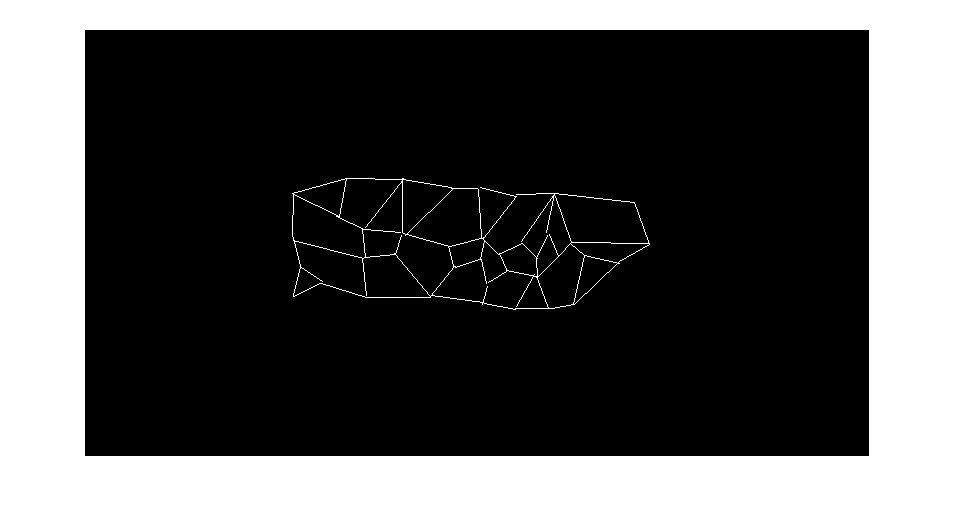

clear;clc;close all



I_gray=imread('1.jpg');
I_gray=imcomplement(I_gray);
level=graythresh(I_gray);  
[height,width]=size(I_gray);
bw=im2bw(I_gray,level);   
figure(1),imshow(bw);      

[L,num]=bwlabel(bw,8);     
plot_x=zeros(1,1);         
plot_y=zeros(1,1);



sum_x=0;sum_y=0;area=0;
[height,width]=size(bw);
for i=1:height
    for j=1:width
        if L(i,j)==1
            sum_x=sum_x+i;
            sum_y=sum_y+j;
            area=area+1;
        end
    end
end



plot_x(1)=fix(sum_x/area);
plot_y(1)=fix(sum_y/area);
figure(2);imshow(bw);

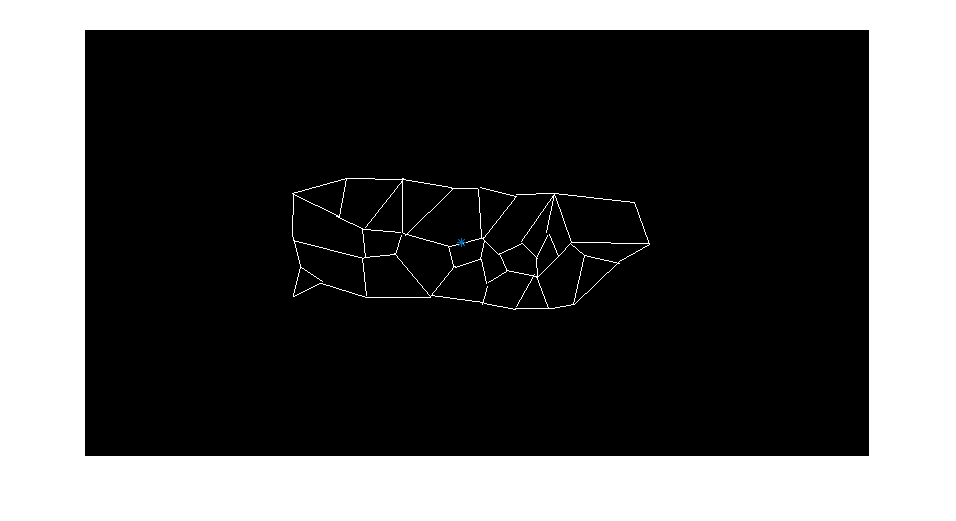



hold on
plot(plot_y(1) ,plot_x(1), '*')


center=[plot_y(1),plot_x(1)];



[row,col,v] = find(bw'==1);
road=[row,height-col];


clearvars -except center road bw I_gray;

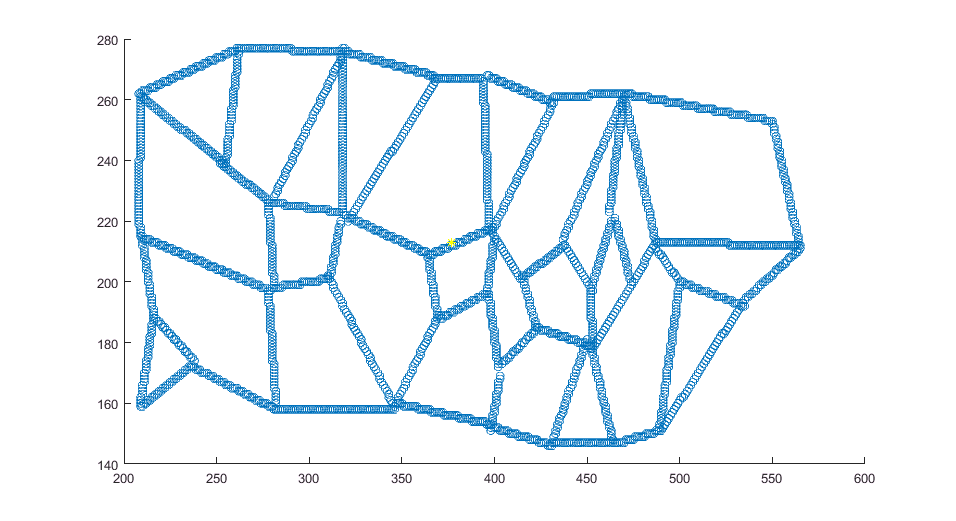

clf;
scatter(road(:,1),road(:,2));
hold on
plot(center(1),center(2),'y*');


[coeff,score,latent]=pca(road)

coeff =     0.9991    0.0428
   -0.0428    0.9991


score =  -118.9480   59.4336
 -117.9489   59.4764
 -116.9498   59.5192
 -115.9507   59.5620
 -114.9517   59.6048
 -113.9526   59.6476
 -112.9535   59.6905
 -111.9544   59.7333
 -110.9553   59.7761
 -109.9562   59.8189


latent =    1.0e+03 *

    9.9228
    1.4212


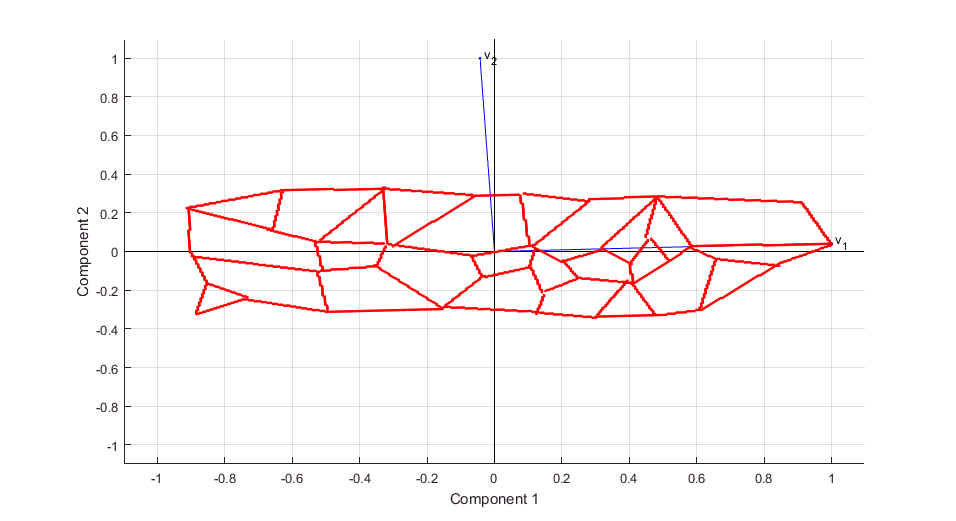

clf;

biplot(coeff(:,1:2),'scores',score(:,1:2),'varlabels',{'v_1','v_2'});

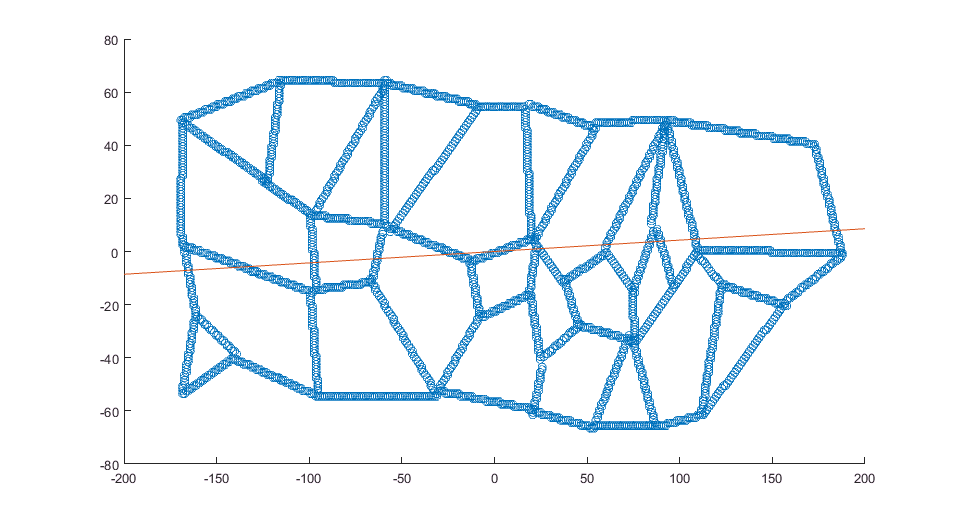


clf;
Xcentered = score*coeff';
scatter(Xcentered(:,1),Xcentered(:,2));
hold on
x=[-200,1/100,200];
y=x./coeff(1,1).*coeff(1,2);
plot(x,y)


distance=sqrt(Xcentered(:,1).*Xcentered(:,1)+Xcentered(:,2).*Xcentered(:,2));
road_side=Xcentered(distance>64,:);

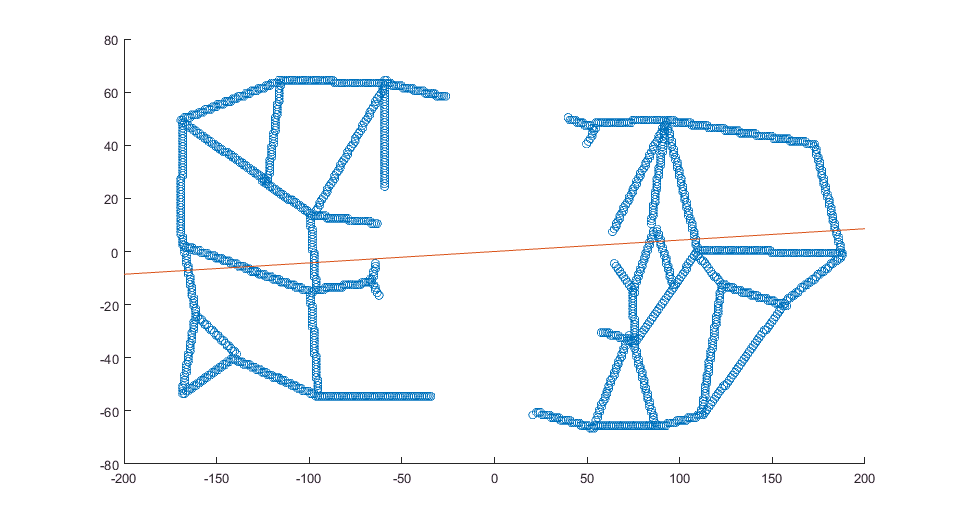

clf;
scatter(road_side(:,1),road_side(:,2));
hold on
x=[-200,1/100,200];
y=x./coeff(1,1).*coeff(1,2);
plot(x,y);


x=[-200:1/10:0];
y=x./coeff(1,1).*coeff(1,2);
i_center=[x',y'];
all_num=[];
for i =1:2001
    distance=sqrt((road_side(:,1)-i_center(i,1)).*(road_side(:,1)-i_center(i,1))+(road_side(:,2)-i_center(i,2)).*(road_side(:,2)-i_center(i,2)));
    num=sum(distance<64);
    all_num=[all_num;num];
end
[m,i]=max(all_num);
left_center=i_center(i,:);
left_center_real=left_center+center;


x=[0:1/10:200];
y=x./coeff(1,1).*coeff(1,2);
i_center=[x',y'];
all_num=[];
for i =1:2001
    distance=sqrt((road_side(:,1)-i_center(i,1)).*(road_side(:,1)-i_center(i,1))+(road_side(:,2)-i_center(i,2)).*(road_side(:,2)-i_center(i,2)));
    num=sum(distance<64);
    all_num=[all_num;num];
end
[m,i]=max(all_num);
right_center=i_center(i,:);
right_center_real=right_center+center;

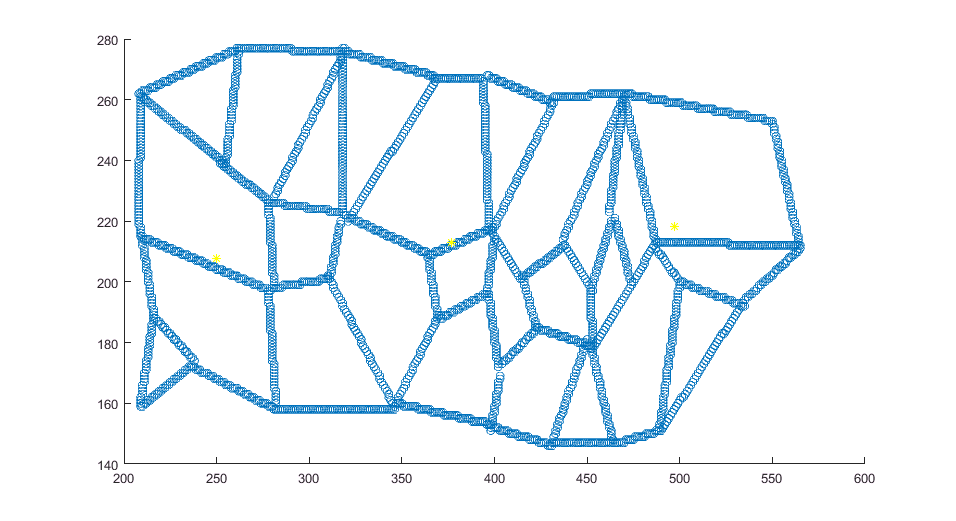

clf;
scatter(road(:,1),road(:,2));
hold on
plot(center(1),center(2),'y*');
hold on
plot(left_center_real(1),left_center_real(2),'y*');
hold on
plot(right_center_real(1),right_center_real(2),'y*');

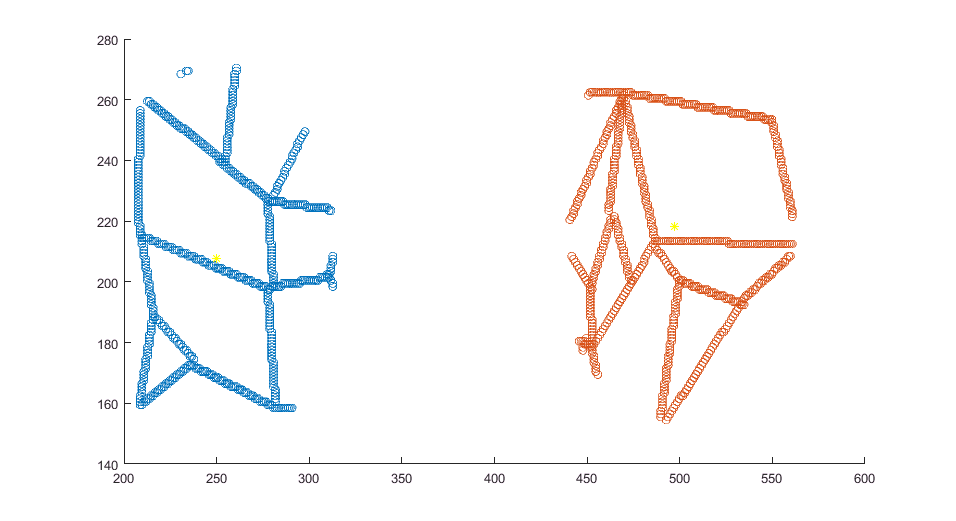


distance=sqrt((road_side(:,1)-left_center(1)).*(road_side(:,1)-left_center(1))+(road_side(:,2)-left_center(2)).*(road_side(:,2)-left_center(2)));
road_in_left=road_side(distance<64,:)+center;
distance=sqrt((road_side(:,1)-right_center(1)).*(road_side(:,1)-right_center(1))+(road_side(:,2)-right_center(2)).*(road_side(:,2)-right_center(2)));
road_in_right=road_side(distance<64,:)+center;
clf;
scatter(road_in_left(:,1),road_in_left(:,2));
hold on
scatter(road_in_right(:,1),road_in_right(:,2));
hold on
plot(left_center_real(1),left_center_real(2),'y*');
hold on
plot(right_center_real(1),right_center_real(2),'y*');

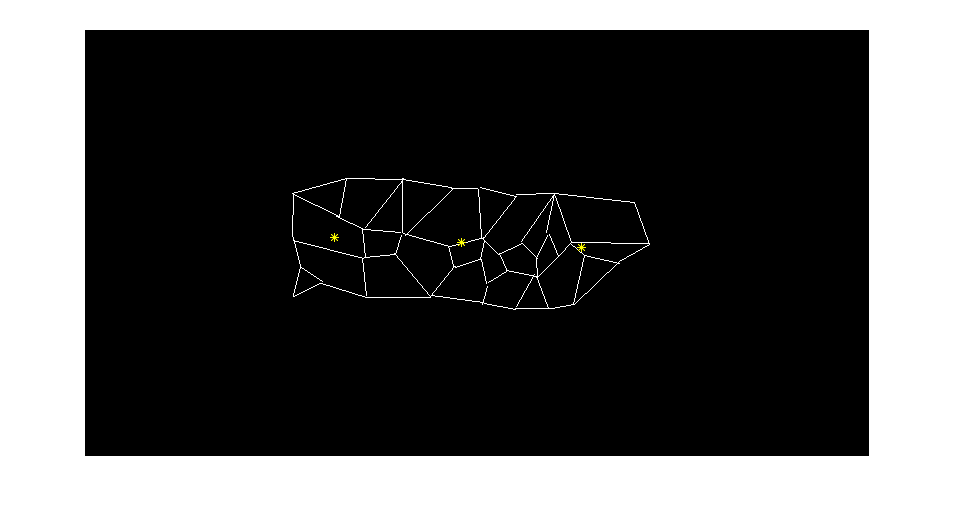

figure(1);imshow(bw);
hold on
plot(center(1),center(2),'y*');
hold on
plot(left_center_real(1),left_center_real(2),'y*');
hold on
plot(right_center_real(1),right_center_real(2),'y*');

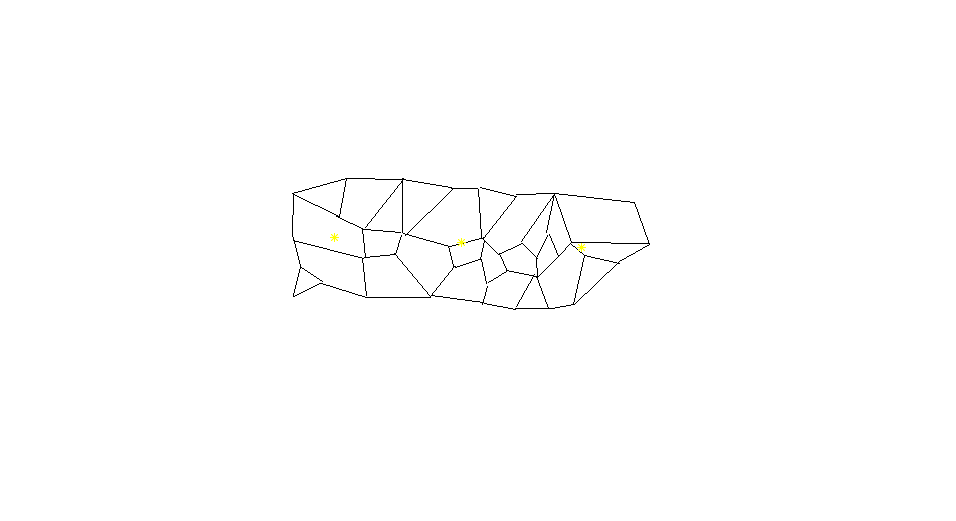

bw=imcomplement(bw);
figure(1);imshow(bw);
hold on
plot(center(1),center(2),'y*');
hold on
plot(left_center_real(1),left_center_real(2),'y*');
hold on
plot(right_center_real(1),right_center_real(2),'y*');